%% Data
filenames1 = {'02-19-2016_15_41_22';
'02-19-2016_15_40_36';
'02-19-2016_15_39_49';
'02-19-2016_15_39_03';
'02-19-2016_15_38_17';
'02-19-2016_15_37_30';
'02-19-2016_15_58_05';
'02-19-2016_15_57_19';
'02-19-2016_15_56_33';
'02-19-2016_15_55_46';
'02-19-2016_15_55_00';
'02-19-2016_15_54_14';
'02-19-2016_15_53_27';
'02-19-2016_15_52_41';
'02-19-2016_15_51_55';
'02-19-2016_15_51_08'};

filenames2 = {'02-19-2016_17_14_43';
'02-19-2016_17_13_57';
'02-19-2016_17_13_10';
'02-19-2016_17_11_57';
'02-19-2016_17_10_24';
'02-19-2016_17_09_38';
'02-19-2016_17_08_51';
'02-19-2016_17_08_05';
'02-19-2016_17_07_19';
'02-19-2016_17_06_32';
'02-19-2016_17_05_46';
'02-19-2016_17_05_00';
'02-19-2016_17_04_14';
'02-19-2016_17_03_27';
'02-19-2016_17_02_41';
'02-19-2016_17_01_55';
'02-19-2016_17_01_08';
'02-19-2016_17_00_22';
'02-19-2016_16_59_36';
'02-19-2016_16_58_49';
'02-19-2016_16_58_03';
'02-19-2016_16_57_17';
'02-19-2016_16_56_30'};

filenames3 = {'02-19-2016_18_15_29'
'02-19-2016_18_11_26'
'02-19-2016_18_10_39'
'02-19-2016_18_09_53'
'02-19-2016_18_09_07'
'02-19-2016_18_08_20'
'02-19-2016_18_03_51'
'02-19-2016_18_01_42'
'02-19-2016_18_00_56'
'02-19-2016_18_00_09'
'02-19-2016_17_56_54'
'02-19-2016_17_56_07'
'02-19-2016_17_55_21'
'02-19-2016_17_54_35'
'02-19-2016_17_53_49'
'02-19-2016_17_53_02'
'02-19-2016_17_49_36'
'02-19-2016_17_48_50'
'02-19-2016_17_48_03'
'02-19-2016_17_47_17'
'02-19-2016_17_46_31'
'02-19-2016_17_45_44'
'02-19-2016_17_44_58'
'02-19-2016_17_44_12'
'02-19-2016_17_43_25'
'02-19-2016_17_42_39'
'02-19-2016_17_41_53'
'02-19-2016_17_41_06'
'02-19-2016_17_40_20'
'02-19-2016_17_39_34'
'02-19-2016_17_38_47'};

% filenames = filenames3;
% filenames = filenames2(1:2);
filenames = [filenames1; filenames2; filenames3];

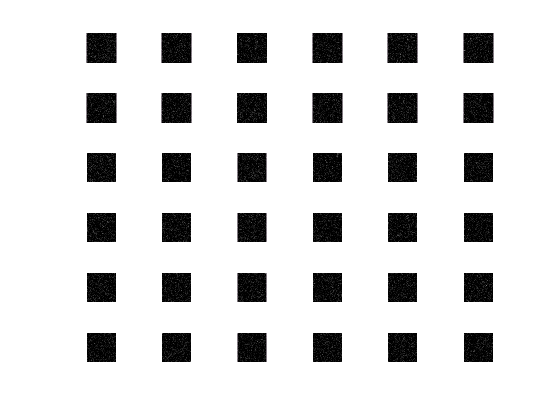

%% Load data
data = cell(size(filenames));
total_atoms = zeros(size(filenames));
center = [129 388]; width = 80;
rect = [center(1)-width/2,center(2)-width/2,width,width];

for i = 1:length(filenames)
    t = imagedata(filenames{i});
%     t.ODcrop = imcrop(t.OD,rect);
%     outp = fit_gaussian_2d_symmetric(t.ODcrop,'plot',0); %[amp, sigma_x, xo, yo, ofset]
%     centern = outp.center + [rect(1), rect(2)];
%     rectn = [centern(1)-width/2,centern(2)-width/2,width,width];
    rectn = [10 100 80 80];    
    t.ODcrop = imcrop(t.OD,rectn);
    t.total = sum(sum(t.ODcrop));
    total_atoms(i) = t.total;
    data{i} = t;
end

%% Temporary
% figure; imshow(t.OD,[0 1]);

%% Visualize data
figure; subplot(6,6,1);
for i = 1:min(36,length(filenames))
    subplot(6,6,i);
    t = data{i};
    imshow(t.ODcrop,[0 2]); set(gca,'YDir','normal');
end

clearvars i center rect t width


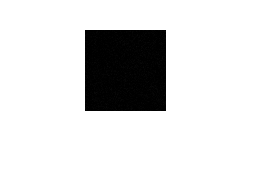

%% Average images all
average_image = getfield(data{1},'ODcrop');
for i = 2:length(data)
    average_image = average_image + getfield(data{i},'ODcrop');
end
average_image = average_image / length(data);
figure;
imshow(average_image,[0 2]); set(gca,'YDir','normal');

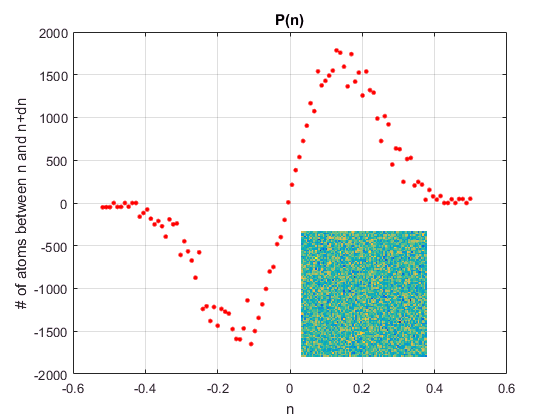

%% P_n
% [n_i,P_n] = extract_Pn(getfield(data{1},'ODcrop'),'bins',100,'plot',0);
[n_i,P_n] = extract_Pn(average_image,'bins',100,'plot',1,'plot_nxy_pos',[0.5 0.15 0.3 0.3]);

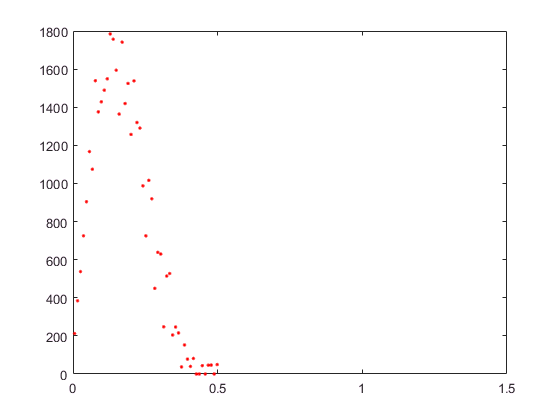

figure; plot(n_i,P_n,'r.'); ylim([0,1800]); xlim([0,1.5]);

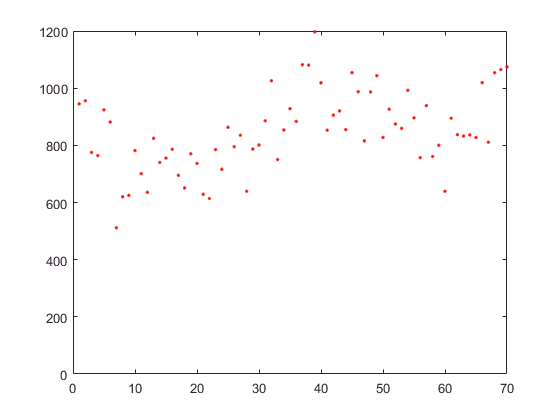

%% Atom number fluctuations
figure; plot(total_atoms,'r.'); ylim([0 1200]);

disp(std(total_atoms))

  138.4631



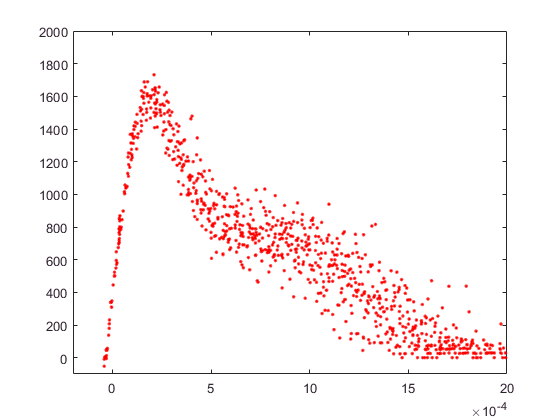

%% Rescaling and P(n)
n_i_all = []; P_n_all = [];
for i = 1:length(data)
    [n_i,P_n] = extract_Pn(getfield(data{i},'ODcrop'),'plot',0,'bins',40);
    n_i = n_i / (sum(sum( getfield(data{1},'ODcrop') )));
    n_i_all = [n_i_all; n_i]; P_n_all = [P_n_all; P_n];
end

figure;
plot(n_i_all,P_n_all,'r.'); ylim([-100 2000]); xlim([-0.2 2]*1e-3);

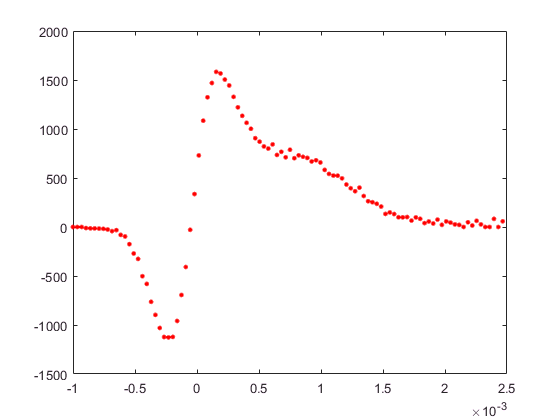

% Binning
n_i_bins = linspace(-1e-3,2.5e-3,101)';
P_n_bins = zeros(100,1);

whichbin = discretize(n_i_all, n_i_bins);
for i = 1:100
    binMembers = P_n_all(whichbin == i);
    if length(binMembers) == 0, P_n_bins(i) = 0; 
    else P_n_bins(i) = mean(binMembers); end
end
n_i_bins = n_i_bins(1:end-1);

figure;
plot(n_i_bins,P_n_bins,'r.','MarkerSize',10);


clearvars i n_i P_n

%% Radial averaging
outp = fit_gaussian_2d_symmetric(average_image,'plot',0);
[radfun,rads] = ExtractRadialFunction(average_image,outp.center,2:1:35);
figure;
plot(rads,radfun,'r.')


%% P(n) from radial integration
outp = fit_gaussian_2d_symmetric(getfield(data{1},'ODcrop'),'plot',0);
[n_r,r_i] = ExtractRadialFunction(average_image,outp.center,2:1:35);
dndr = zeros(size(n_r));
for i = 1:length(r_i)
    t = 2;
    p = polyfit(r_i(max(1,i-t):min(length(r_i),i+t)), n_r(max(1,i-t):min(length(r_i),i+t)), 2);
    dndr(i) = polyval(polyder(p),r_i(i));
end
P_n_r = abs(2*pi*r_i.*n_r./ dndr);
figure;
plot(n_r,P_n_r,'r.'); ylim([0 1500]);
